## DGDE Week 1

clc; clear;

v1 = rand(3,1)'*10

v1 =     8.6919    5.3086    2.3273


v2 = rand(3,1)'*10

v2 =     0.1140    4.3047    4.0235



v1/norm(v1)

ans =     0.8320    0.5081    0.2228


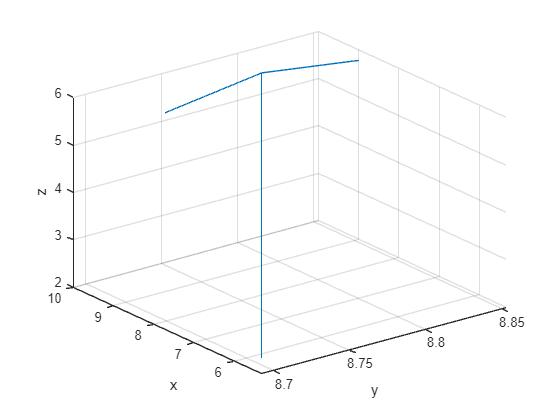



figure
quiver3(v1(1),v1(2),v1(3),v2(1),v2(2),v2(3))


zlabel("z");
ylabel("x");
xlabel("y");


dot(v1,v2)

ans = 33.2063


% x1x2;y1y2;z1z2
v1 = [1,4;1,1;0,0]

v1 =      1     4
     1     1
     0     0


v2 = [1,3;1,3;0,0]

v2 =      1     3
     1     3
     0     0



% x1y1z1;x2y2z2
v1 = [1 1 0; 4 1 1]

v1 =      1     1     0
     4     1     1


v2 = [1 1 0; 3 3 1]

v2 =      1     1     0
     3     3     1



v3 = cross(v1,v2)

v3 =      0     0     0
    -2    -1     9


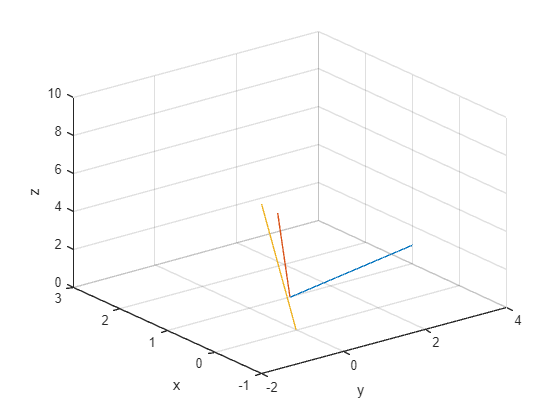


figure
plot3(v1(:,1),v1(:,2),v1(:,3))

hold on
plot3(v2(:,1),v2(:,2),v2(:,3))
plot3(v3(:,1),v3(:,2),v3(:,3))
hold off

grid()
zlabel("z");
ylabel("x");
xlabel("y");

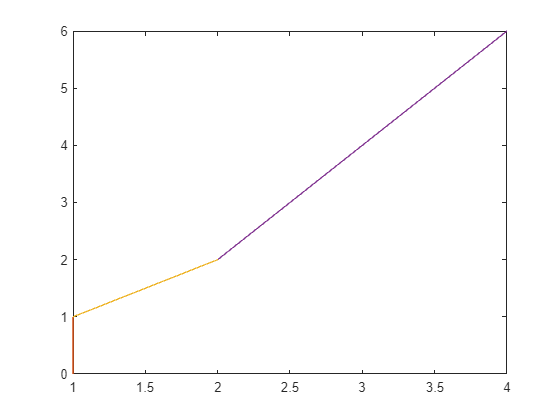

% Vector function

vfun = @(x,y) [y,x^2];

Startcords = [1,0];
startval = vfun(Startcords(1),Startcords(2));

NewVal = Startcords+startval;

figure

plot([NewVal(1), Startcords(1)], [NewVal(2), Startcords(2)])

i = 0;
nsteps = 3;

while i < nsteps
    i = i+1;

    NewVal = Startcords+startval;

    hold on
    plot([NewVal(1), Startcords(1)], [NewVal(2), Startcords(2)])

    drawnow

    hold off

    Startcords = NewVal;
    startval = vfun(NewVal(1),NewVal(2));


end

## Lecture notes opgaver

a = [1,1,1];
b = [1,2,1];

% Opgave 1
l1 = cross(a,b), l1b = cross(a, l1), l1c = cross(l1b, l1b)

l1 =     -1     0     1


l1b =      1    -2     1


l1c =      0     0     0



% Opgave 2

% c)
syms t
vvec = [2*t,0,0]

$$vvec = \left(\begin{array}{ccc} 2\,t & 0 & 0 \end{array}\right)$$

avec = [2,0,0]

avec =      2     0     0



dot(avec,vvec)

$$ans = 4\,t$$


norm(vvec)

$$ans = \sqrt{4\,{\left|t\right|}^{2}}$$